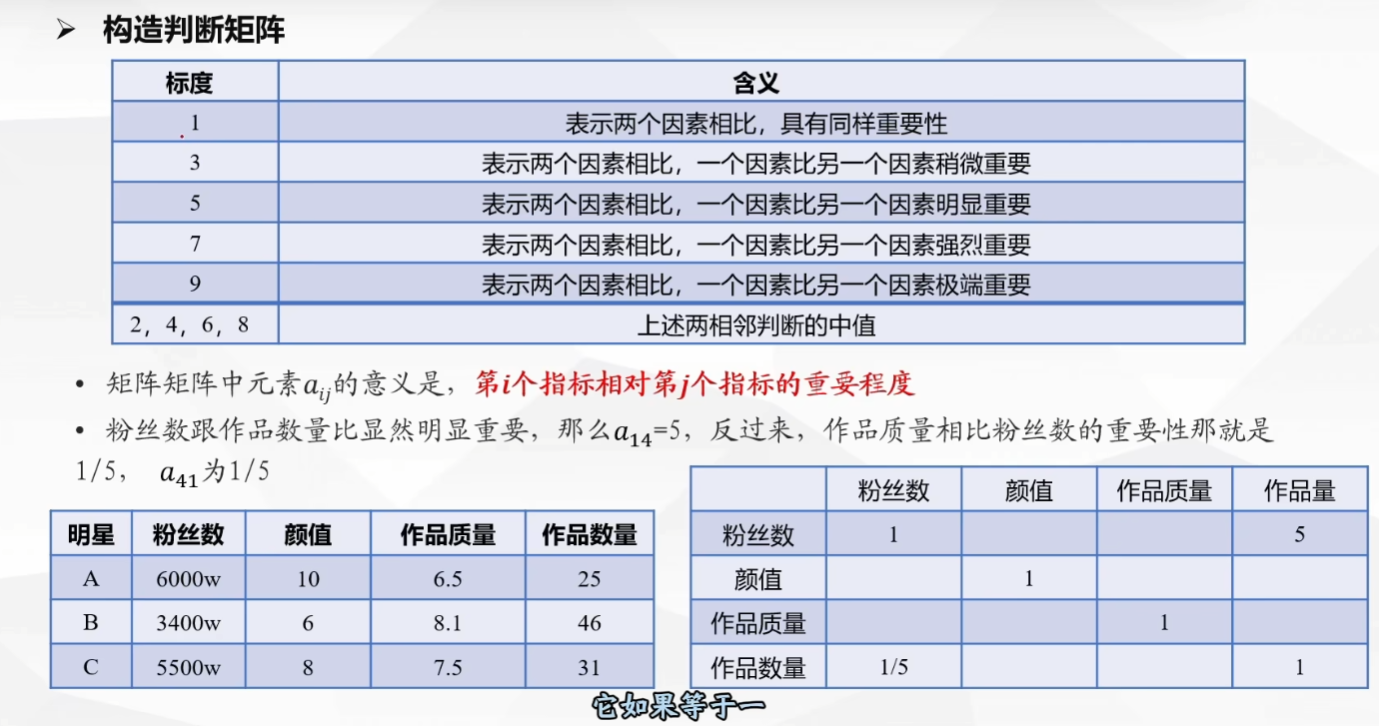

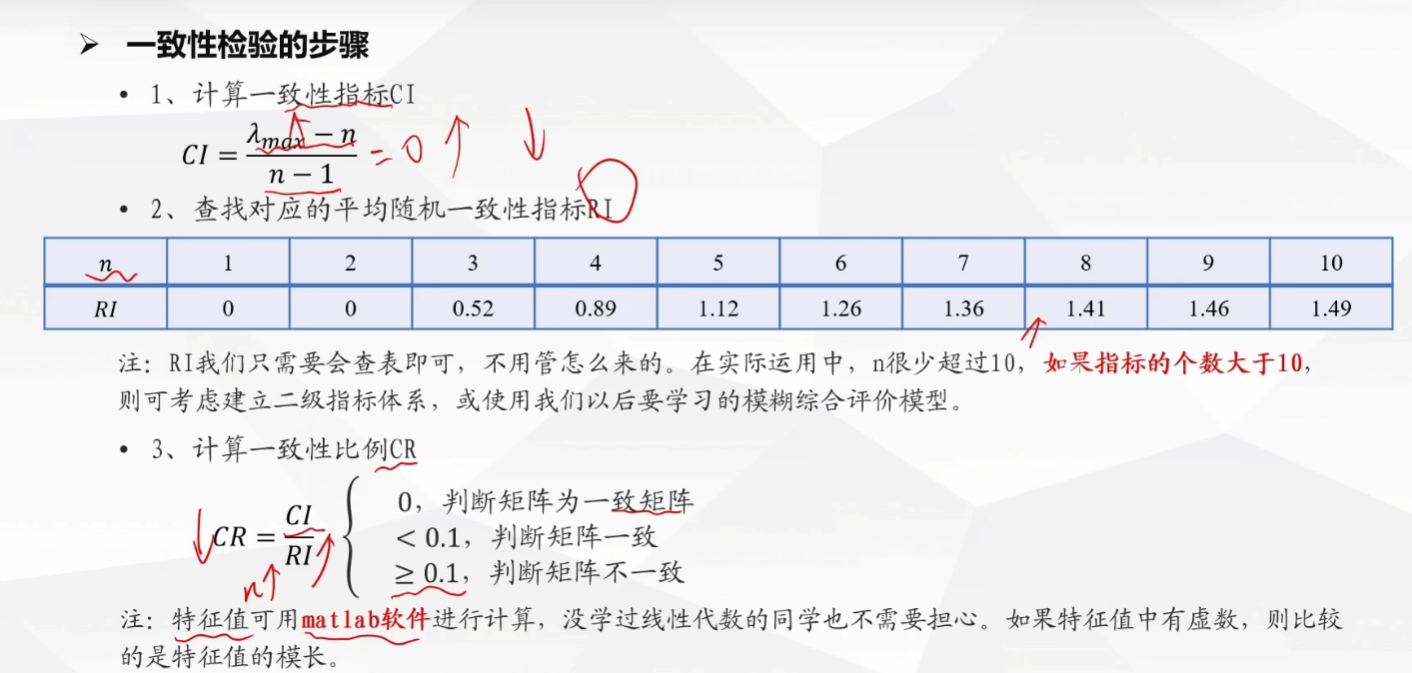

一致性检验

clc,clear;
%A=[1 2 3 5;1/2 1 1/2 2;1/3 2 1 1/2;1/5 1/2 2 1];
%A=[1 2 3 5;1/2 1 1/2 2;1/3 2 1 2;1/5 1/2 1/2 1];
A = input('输入判断矩阵A=');
[n,n]=size(A);
[V,D]=eig(A);   %V是特征向量，D是特征值
Max_eig=max(max(D));
CI=(Max_eig-n)/(n-1);
RI=[0 0 0.52 0.89 1.12 1.26 1.36 1.41 1.46 0.49 0.52 1.54 1.56 1.58 1.59];
CR=CI/RI(n);
disp('一致性指标CI=');disp(CI);
disp('一致性指标CR=');disp(CR);
if CR<0.10
    disp('一致性可接受')
else
    disp('一致性不可接受')
end

算术平均法计算权重

%A=[1 2 3 5;1/2 1 1/2 2;1/3 2 1 2;1/5 1/2 1/2 1];
A = input('输入判断矩阵A=');
Asum=sum(A,1);
[n,n]=size(A);
Ar=repmat(Asum,n,1);
Stand_A=A./Ar;
ASumr=sum(Stand_A,2);
disp(ASumr/n);

几何平均法算权重

%A=[1 2 3 5;1/2 1 1/2 2;1/3 2 1 2;1/5 1/2 1/2 1];
A = input('输入判断矩阵A=');
[n,n]=size(A);
prod_A=prod(A,2);
prod_n_A=prod_A.^(1/n);
re_prod_A=prod_n_A./sum(prod_n_A);
disp(re_prod_A);

    0.4949
    0.1778
    0.2272
    0.1000

